CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])


load('ContourData_S_EE=0.024_7D.mat','ContourData_7D')

## All S_II slices

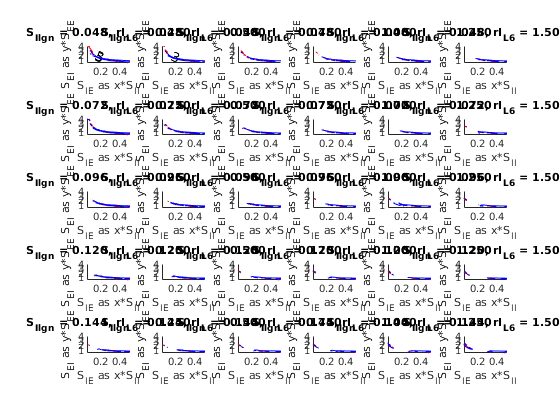

S_EEnow = ContourData_7D.S_EE;
S_IInow = ContourData_7D.S_II;
figure(1)
for S_IlgnInd = 1:ContourData_7D.PanelNum1
    S_Ilgnnow = ContourData_7D.S_Ilgntest(S_IlgnInd);
    for rI_L6Ind = 1:ContourData_7D.PanelNum2
        rI_L6now = ContourData_7D.rI_L6test(rI_L6Ind);
        
    subplot(ContourData_7D.PanelNum1, ContourData_7D.PanelNum2, rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
    hold on
    CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,:,S_IlgnInd,rI_L6Ind)); CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,:,S_IlgnInd,rI_L6Ind)); CurrentFrI(CurrentFrI<eps) = nan;
    [C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
                     CurrentFrE,[3  5 ],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
    [C2,h2]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
                     CurrentFrI,[10 18],'ShowText','on','color','b');
    clabel(C2,h2,'FontSize',10,'Color','k')
    hold off
    S_Ilgntxt = sprintf('%.3f',S_Ilgnnow);
    rI_L6txt = sprintf('%.3f',rI_L6now);
    title(['S_{Ilgn} = ' S_Ilgntxt ', rI_{L6} = ' rI_L6txt ])
    xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
    %xlim([0.06 0.5])
    end
end

## parameters

sprintf(['S_EE = %.3f, S_II = %.3f, S_Elgn = %.3f, S_amb = %.3f, S_EL6 = %.3f, S_IL6 = %.3f\n',...
         'r_Elgn = %.3f, r_Ilgn = %.3f, r_Eamb = %.3f, r_Iamb = %.3f, r_EL6 = %.3f'],...
         ContourData_7D.S_EE, ContourData_7D.S_II, ContourData_7D.S_Elgn, ContourData_7D.S_amb, ContourData_7D.S_EL6, ContourData_7D.S_IL6,...
         ContourData_7D.lambda_E, ContourData_7D.lambda_I, ContourData_7D.rE_amb, ContourData_7D.rI_amb, ContourData_7D.rE_L6)


## Check single contourmap

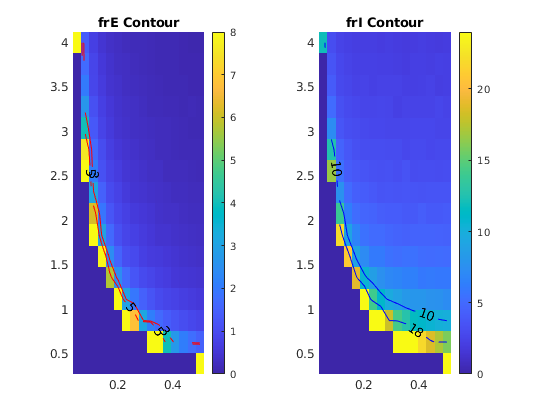

S_IlgnInd = 1; rI_L6Ind = 2;
S_Ilgnnow = ContourData_7D.S_Ilgntest(S_IlgnInd);
rI_L6now = ContourData_7D.rI_L6test(rI_L6Ind);
    CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,:,S_IlgnInd,rI_L6Ind)); %CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,:,S_IlgnInd,rI_L6Ind)); %CurrentFrI(CurrentFrI<eps) = nan;
figure('Name','Check Single Contour')
subplot 121
hold on
imagesc(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,CurrentFrE)
set(gca,'Ydir','Normal')
CurrentFrE(CurrentFrE<eps) = nan;
[C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
                     CurrentFrE,[3  5 ],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
hold off
colorbar; caxis([0 8])
title('frE Contour')

subplot 122
hold on
imagesc(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,CurrentFrI)
set(gca,'Ydir','Normal')
CurrentFrI(CurrentFrI<eps) = nan;
[C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
                     CurrentFrI,[10  18 ],'ShowText','on','color','b');
    clabel(C1,h1,'FontSize',10,'Color','k')
hold off
colorbar; caxis([0 24])
title('frI Contour')

figure(2)
% S_EIInd = [11,22];
% S_IEInd = [5 15]; % for ContourData_S_EE=0.029_3D.mat

S_EIInd = [11,22];
S_IEInd = [4 10]; % for ContourData_S_EE=0.024_3D_expandSII.mat

% S_EIInd = [14,27];
% S_IEInd = [5 13]; % for ContourData_S_EE=0.029_3D_expandSII.mat

% fix S_EI, change S_IE
for plotInd = 1:2
    ei = S_EIInd(plotInd);
    subplot(2,2,plotInd)
    hold on
    CurrentFrE = squeeze(ContourData_3D.Fr_NoFix(1,ei,:,:)); CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrI = squeeze(ContourData_3D.Fr_NoFix(2,ei,:,:)); CurrentFrI(CurrentFrI<eps) = nan;
%     CurrentFrE = permute(CurrentFrE,[2 1]);
%     CurrentFrI = permute(CurrentFrI,[2 1]); % S_II first, so it will be on y axis
    [C1,h1]= contour(ContourData_3D.S_IItest,ContourData_3D.S_IEtest,...
                     CurrentFrE,[2 5],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
    [C2,h2]= contour(ContourData_3D.S_IItest,ContourData_3D.S_IEtest,...
                     CurrentFrI,[7 10 15],'ShowText','on','color','b');
    clabel(C2,h2,'FontSize',10,'Color','k')
    
        hold off
    S_EItxt = sprintf('%.3f',ContourData_3D.S_EItest(ei));
    title(['S_{EE} = 0.024, S_{EI} = ' S_EItxt ])
    xlabel('S_{II}');ylabel('S_{IE}')
end

% fix S_IE, change S_EI
for plotInd = 1:2
    ie = S_IEInd(plotInd);
    subplot(2,2,2+plotInd)
    hold on
    CurrentFrE = squeeze(ContourData_3D.Fr_NoFix(1,:,ie,:)); CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrI = squeeze(ContourData_3D.Fr_NoFix(2,:,ie,:)); CurrentFrI(CurrentFrI<eps) = nan;
%     CurrentFrE = permute(CurrentFrE,[2 1]);
%     CurrentFrI = permute(CurrentFrI,[2 1]); % S_II first, so it will be on y axis
    [C1,h1]= contour(ContourData_3D.S_IItest,ContourData_3D.S_EItest,...
                     CurrentFrE,[2 5],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
    [C2,h2]= contour(ContourData_3D.S_IItest,ContourData_3D.S_EItest,...
                     CurrentFrI,[7 10 15],'ShowText','on','color','b');
    clabel(C2,h2,'FontSize',10,'Color','k')
    
        hold off
    S_IEtxt = sprintf('%.3f',ContourData_3D.S_IEtest(ie));
    title(['S_{EE} = 0.029, S_{EI} = ' S_IEtxt ])
    xlabel('S_{II}');ylabel('S_{EI}')
end

figure(3)
% rEamb = 720; rIamb = 360
load('ContourData_S_EE=0.024_3D_expandSII_AllMultipliers.mat','ContourData_3D')
S_EEnow = 0.024;
S_IIIndList = [5 11 16 21 26];
for PlotInd = 1:5
    S_IIInd = S_IIIndList(PlotInd);
    S_IInow = ContourData_3D.S_IItest(S_IIInd);
    subplot(3,5,PlotInd)
    hold on
    CurrentFrE = squeeze(ContourData_3D.Fr_NoFix(1,:,:,S_IIInd)); CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrI = squeeze(ContourData_3D.Fr_NoFix(2,:,:,S_IIInd)); CurrentFrI(CurrentFrI<eps) = nan;
    [C1,h1]= contour(ContourData_3D.S_IEtestMtp_of_S_II,ContourData_3D.S_EItest/S_EEnow,...
                     CurrentFrE,[2 5],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
    [C2,h2]= contour(ContourData_3D.S_IEtestMtp_of_S_II,ContourData_3D.S_EItest/S_EEnow,...
                     CurrentFrI,[7 15],'ShowText','on','color','b');
    clabel(C2,h2,'FontSize',10,'Color','k')
    hold off
    S_EEtxt = sprintf('%.3f',S_EEnow);
    S_IItxt = sprintf('%.3f',ContourData_3D.S_IItest(S_IIInd));
    title(['S_{EE} = ' S_EEtxt ', S_{II} = ' S_IItxt ])
    xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
    xlim([0.06 0.5])
end

% rEamb = 540; rIamb = 540
load('ContourData_S_EE=0.024_3D_rIamb540.mat','ContourData_3D')
S_EEnow = 0.024;
S_IIIndList = 3:3:15;
for PlotInd = 1:5
    S_IIInd = S_IIIndList(PlotInd);
    S_IInow = ContourData_3D.S_IItest(S_IIInd);
    subplot(3,5,PlotInd+5)
    hold on
    CurrentFrE = squeeze(ContourData_3D.Fr_NoFix(1,:,:,S_IIInd)); CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrI = squeeze(ContourData_3D.Fr_NoFix(2,:,:,S_IIInd)); CurrentFrI(CurrentFrI<eps) = nan;
    [C1,h1]= contour(ContourData_3D.S_IEtestMtp_of_S_II,ContourData_3D.S_EItest/S_EEnow,...
                     CurrentFrE,[2 5],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
    [C2,h2]= contour(ContourData_3D.S_IEtestMtp_of_S_II,ContourData_3D.S_EItest/S_EEnow,...
                     CurrentFrI,[7 15],'ShowText','on','color','b');
    clabel(C2,h2,'FontSize',10,'Color','k')
    hold off
    S_EEtxt = sprintf('%.3f',S_EEnow);
    S_IItxt = sprintf('%.3f',ContourData_3D.S_IItest(S_IIInd));
    title(['S_{EE} = ' S_EEtxt ', S_{II} = ' S_IItxt ])
    xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
    xlim([0.06 0.5])
end

% rEamb = 540; rIamb = 0
load('ContourData_S_EE=0.024_3D_rIamb0.mat','ContourData_3D')
S_EEnow = 0.024;
S_IIIndList = 3:3:15;
for PlotInd = 1:5
    S_IIInd = S_IIIndList(PlotInd);
    S_IInow = ContourData_3D.S_IItest(S_IIInd);
    subplot(3,5,PlotInd+10)
    hold on
    CurrentFrE = squeeze(ContourData_3D.Fr_NoFix(1,:,:,S_IIInd)); CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrI = squeeze(ContourData_3D.Fr_NoFix(2,:,:,S_IIInd)); CurrentFrI(CurrentFrI<eps) = nan;
    [C1,h1]= contour(ContourData_3D.S_IEtestMtp_of_S_II,ContourData_3D.S_EItest/S_EEnow,...
                     CurrentFrE,[2 5],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
    [C2,h2]= contour(ContourData_3D.S_IEtestMtp_of_S_II,ContourData_3D.S_EItest/S_EEnow,...
                     CurrentFrI,[7 15],'ShowText','on','color','b');
    clabel(C2,h2,'FontSize',10,'Color','k')
    hold off
    S_EEtxt = sprintf('%.3f',S_EEnow);
    S_IItxt = sprintf('%.3f',ContourData_3D.S_IItest(S_IIInd));
    title(['S_{EE} = ' S_EEtxt ', S_{II} = ' S_IItxt ])
    xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
    xlim([0.06 0.5])
end
